# Reto F3001C

Max Eduardo Garcia Esquivel - A01236070.

   %Code Variables
%Sizes
sXs = [1000,930,475,405];
sYs = [325,235,955,730];

%Paths
SuperiorPath = "./../Phase4V2/Sweeps/Matlab/";
FundamentalPath = "./../Phase3/Sweeps/Matlab/";

%Modes
Superior = "Waveguide%i_%i_532_Mode%i";
Fundamental = "Waveguide%i_%i_1596";
ModesSup = [15,9,19,12];

warning('off','MATLAB:polyfit:RepeatedPointsOrRescale')

## Waveguide selector:

sel = 2;
nmodes = ModesSup(sel);
mode = 9;
disp("Selected waveguide:")

Selected waveguide:


disp("   Size: "+num2str(sXs(sel))+"x"+num2str(sYs(sel)));

   Size: 930x235


disp("   Mode: "+num2str(mode));

   Mode: 9


## Waveguide Summary:

disp("Waveguide: "+num2str(sXs(sel))+"x"+num2str(sXs(sel))+", mode: "+num2str(ModesSup(sel)));

Waveguide: 930x930, mode: 9


### Fundamental Mode Data (1596nm):

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
l = wgFundamental.lambdaData;
w = wgFundamental.omegaData;
neff = wgFundamental.neffData;

#### Ranges:

disp("Lambda Ranges: "+num2str(min(l))+"-"+num2str(max(l))+"");

Lambda Ranges: 1.53-1.596


disp("Omega Ranges: "+num2str(min(w))+"-"+num2str(max(w))+"");

Omega Ranges: 1181049869.7706-1231997119.0548


#### Neff vs ω/λ

disp("Function neff(λ):");

Function neff(λ):


disp(wgFundamental.nefflStr);

0.000030705937210545883396094896*l.^30-0.000238501771845040964285106222*l.^29+0.000498347405939057221113674956*l.^28+0.000425245917695831257814703674*l.^27-0.002121487566737789102339073466*l.^26-0.000196366185031919077358733561*l.^25+0.002717789480257208536290169931*l.^24+0.004748571853186343665054192087*l.^23-0.003517864012279328916193987808*l.^22-0.016884928584547334584620159603*l.^21+0.034262248319043474287237671660*l.^20-0.057203641697408560973237001690*l.^19+0.002907604281785848392150040098*l.^18+0.145470591190064307829388212667*l.^17-0.128515855730241157495186143933*l.^16+0.011163167845660522392581270879*l.^15+0.054478577343274076083545764959*l.^14+0.010957849189462838188080517909*l.^13+0.647261617069250116962564334244*l.^12-3.555904876160217220615322730737*l.^11+3.869128055884281991438911063597*l.^10-1.884337913028687250260873042862*l.^9+4.724117647900090588564125937410*l.^8+9.966953951908914532964445243124*l.^7-41.169879006622274175697384634987*l.^6+35.6553417797740408445861248

disp("Function neff(ω)");

Function neff(ω)


disp(wgFundamental.neffwStr);

8.502026705724635180928932788110e-273*w.^30-1.173671773238715913640420574474e-262*w.^29+4.615075111166472813834691290258e-253*w.^28-8.757738774680932914685026993765e-244*w.^27+1.055613769871649052698941652054e-234*w.^26-7.961912731654153242421072370981e-226*w.^25+4.377956583019456102925565481114e-217*w.^24-2.392886351488539177035328703129e-207*w.^23+5.289850812899921045822893640904e-198*w.^22+1.413971499049219245639330422065e-190*w.^21-1.084226176729071065060960126697e-179*w.^20+7.789973589596243333127466099919e-171*w.^19+4.258261823883678297759377478331e-163*w.^18+1.112978703030809713037041353022e-152*w.^17-1.391470365889074892209636767129e-143*w.^16+2.218056180382216141282514538553e-135*w.^15-2.434457911279972345886108949362e-125*w.^14+2.185762590433994041796226368519e-116*w.^13-1.260881945056160523878067900026e-107*w.^12+8.188134024651755956490540139644e-98*w.^11-2.403278973677587136327321942917e-89*w.^10-1.010354392208293854846964475703e-79*w.^9+2.141534807420706243068432890441e-71

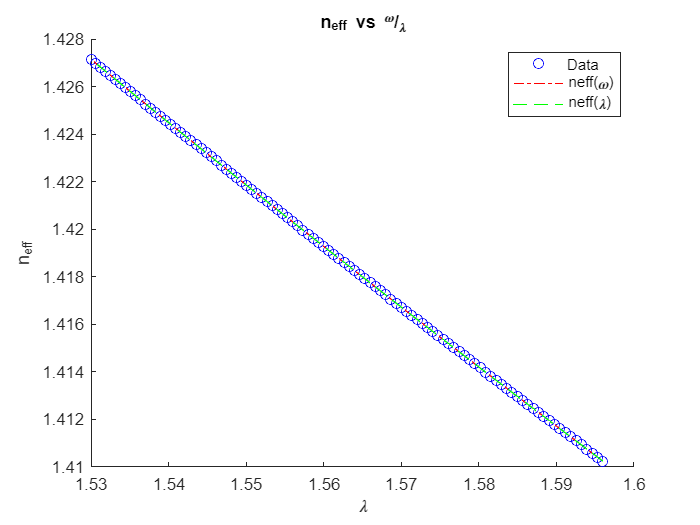

figure;
hold on
title("n_{eff} vs ^{\omega}/_{\lambda}");
plot(l,neff,'bo',l,wgFundamental.neffwFun(w),'r-.',l,wgFundamental.nefflFun(l),'g--');
legend(["Data","neff(\omega)","neff(\lambda)"]);
xlabel("\lambda");
ylabel("n_{eff}");
hold off

#### Subfunctions (k, dw, Vg, d2w, D)

disp("Function k(ω):");

Function k(ω):


disp(wgFundamental.kwStr);

w.*(8.502026705724635180928932788110e-273*w.^30-1.173671773238715913640420574474e-262*w.^29+4.615075111166472813834691290258e-253*w.^28-8.757738774680932914685026993765e-244*w.^27+1.055613769871649052698941652054e-234*w.^26-7.961912731654153242421072370981e-226*w.^25+4.377956583019456102925565481114e-217*w.^24-2.392886351488539177035328703129e-207*w.^23+5.289850812899921045822893640904e-198*w.^22+1.413971499049219245639330422065e-190*w.^21-1.084226176729071065060960126697e-179*w.^20+7.789973589596243333127466099919e-171*w.^19+4.258261823883678297759377478331e-163*w.^18+1.112978703030809713037041353022e-152*w.^17-1.391470365889074892209636767129e-143*w.^16+2.218056180382216141282514538553e-135*w.^15-2.434457911279972345886108949362e-125*w.^14+2.185762590433994041796226368519e-116*w.^13-1.260881945056160523878067900026e-107*w.^12+8.188134024651755956490540139644e-98*w.^11-2.403278973677587136327321942917e-89*w.^10-1.010354392208293854846964475703e-79*w.^9+2.141534807420706243068432890441

disp("Function dk(ω)/dω:");

Function dk(ω)/dω:


disp(wgFundamental.dkwdwStr);

(8.502026705724635180928932788110e-273*w.^30*(31)-1.173671773238715913640420574474e-262*w.^29*(30)+4.615075111166472813834691290258e-253*w.^28*(29)-8.757738774680932914685026993765e-244*w.^27*(28)+1.055613769871649052698941652054e-234*w.^26*(27)-7.961912731654153242421072370981e-226*w.^25*(26)+4.377956583019456102925565481114e-217*w.^24*(25)-2.392886351488539177035328703129e-207*w.^23*(24)+5.289850812899921045822893640904e-198*w.^22*(23)+1.413971499049219245639330422065e-190*w.^21*(22)-1.084226176729071065060960126697e-179*w.^20*(21)+7.789973589596243333127466099919e-171*w.^19*(20)+4.258261823883678297759377478331e-163*w.^18*(19)+1.112978703030809713037041353022e-152*w.^17*(18)-1.391470365889074892209636767129e-143*w.^16*(17)+2.218056180382216141282514538553e-135*w.^15*(16)-2.434457911279972345886108949362e-125*w.^14*(15)+2.185762590433994041796226368519e-116*w.^13*(14)-1.260881945056160523878067900026e-107*w.^12*(13)+8.188134024651755956490540139644e-98*w.^11*(12)-2.403278973677587136

disp("Function Vg(ω):");

Function Vg(ω):


disp(wgFundamental.vgwStr);

(3*10^8)./(8.502026705724635180928932788110e-273*w.^30*(31)-1.173671773238715913640420574474e-262*w.^29*(30)+4.615075111166472813834691290258e-253*w.^28*(29)-8.757738774680932914685026993765e-244*w.^27*(28)+1.055613769871649052698941652054e-234*w.^26*(27)-7.961912731654153242421072370981e-226*w.^25*(26)+4.377956583019456102925565481114e-217*w.^24*(25)-2.392886351488539177035328703129e-207*w.^23*(24)+5.289850812899921045822893640904e-198*w.^22*(23)+1.413971499049219245639330422065e-190*w.^21*(22)-1.084226176729071065060960126697e-179*w.^20*(21)+7.789973589596243333127466099919e-171*w.^19*(20)+4.258261823883678297759377478331e-163*w.^18*(19)+1.112978703030809713037041353022e-152*w.^17*(18)-1.391470365889074892209636767129e-143*w.^16*(17)+2.218056180382216141282514538553e-135*w.^15*(16)-2.434457911279972345886108949362e-125*w.^14*(15)+2.185762590433994041796226368519e-116*w.^13*(14)-1.260881945056160523878067900026e-107*w.^12*(13)+8.188134024651755956490540139644e-98*w.^11*(12)-2.40327897

disp("Function d2k(ω)/dω:");

Function d2k(ω)/dω:


disp(wgFundamental.d2kwdw2Str);

(8.502026705724635180928932788110e-273*w.^29*(930)-1.173671773238715913640420574474e-262*w.^28*(870)+4.615075111166472813834691290258e-253*w.^27*(812)-8.757738774680932914685026993765e-244*w.^26*(756)+1.055613769871649052698941652054e-234*w.^25*(702)-7.961912731654153242421072370981e-226*w.^24*(650)+4.377956583019456102925565481114e-217*w.^23*(600)-2.392886351488539177035328703129e-207*w.^22*(552)+5.289850812899921045822893640904e-198*w.^21*(506)+1.413971499049219245639330422065e-190*w.^20*(462)-1.084226176729071065060960126697e-179*w.^19*(420)+7.789973589596243333127466099919e-171*w.^18*(380)+4.258261823883678297759377478331e-163*w.^17*(342)+1.112978703030809713037041353022e-152*w.^16*(306)-1.391470365889074892209636767129e-143*w.^15*(272)+2.218056180382216141282514538553e-135*w.^14*(240)-2.434457911279972345886108949362e-125*w.^13*(210)+2.185762590433994041796226368519e-116*w.^12*(182)-1.260881945056160523878067900026e-107*w.^11*(156)+8.188134024651755956490540139644e-98*w.^10*(132)-

disp("Function D(ω):");

Function D(ω):


disp(wgFundamental.DwStr);

-(w.^2/(2*pi*3*10^8)).*((8.502026705724635180928932788110e-273*w.^29*(930)-1.173671773238715913640420574474e-262*w.^28*(870)+4.615075111166472813834691290258e-253*w.^27*(812)-8.757738774680932914685026993765e-244*w.^26*(756)+1.055613769871649052698941652054e-234*w.^25*(702)-7.961912731654153242421072370981e-226*w.^24*(650)+4.377956583019456102925565481114e-217*w.^23*(600)-2.392886351488539177035328703129e-207*w.^22*(552)+5.289850812899921045822893640904e-198*w.^21*(506)+1.413971499049219245639330422065e-190*w.^20*(462)-1.084226176729071065060960126697e-179*w.^19*(420)+7.789973589596243333127466099919e-171*w.^18*(380)+4.258261823883678297759377478331e-163*w.^17*(342)+1.112978703030809713037041353022e-152*w.^16*(306)-1.391470365889074892209636767129e-143*w.^15*(272)+2.218056180382216141282514538553e-135*w.^14*(240)-2.434457911279972345886108949362e-125*w.^13*(210)+2.185762590433994041796226368519e-116*w.^12*(182)-1.260881945056160523878067900026e-107*w.^11*(156)+8.18813402465175595649054

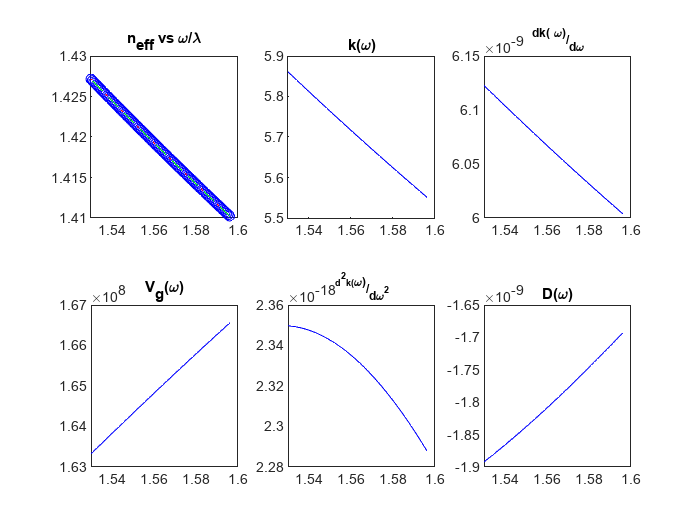

subplot(2,3,1);
plot(l,neff,'bo',l,wgFundamental.neffwFun(w),'r-.',l,wgFundamental.nefflFun(l),'g--');
title("n_{eff} vs \omega/\lambda");
subplot(2,3,2);
plot(l,wgFundamental.kwFun(w),'b');
title("k(\omega)");
subplot(2,3,3);
plot(l,wgFundamental.dkwdwFun(w),'b');
title("^{dk(\omega)}/_{d\omega}");
subplot(2,3,4);
plot(l,wgFundamental.vgwFun(w),'b');
title("V_g(\omega)");
subplot(2,3,5);
plot(l,wgFundamental.d2kwdw2Fun(w),'b');
title("^{d^2k(\omega)}/_{d\omega^2}");
subplot(2,3,6);
plot(l,wgFundamental.DwFun(w),'b');
title("D(\omega)");

### Superior Mode Data (530nm):

file = sprintf(Superior,sXs(sel),sYs(sel),ModesSup(sel));
load(SuperiorPath+file);
wgSuperior = waveguide(lambda,neff);
l = wgSuperior.lambdaData;
w = wgSuperior.omegaData;
neff = wgSuperior.neffData;

#### Ranges:

disp("Lambda Ranges: "+num2str(min(l))+"-"+num2str(max(l))+"");

Lambda Ranges: 0.51-0.532


disp("Omega Ranges: "+num2str(min(w))+"-"+num2str(max(w))+"");

Omega Ranges: 3543149609.3118-3695991357.1645


#### Neff vs ω/λ

disp("Function neff(λ):");

Function neff(λ):


disp(wgSuperior.nefflStr);

-1306649727839.864013671875000000000000000000*l.^30+7069181280086.175781250000000000000000000000*l.^29-11167879879376.021484375000000000000000000000*l.^28+7363788858541.758789062500000000000000000000*l.^27-1664366774868.049316406250000000000000000000*l.^26-1052909399143.172729492187500000000000000000*l.^25+1234085043173.134521484375000000000000000000*l.^24-157142139346.363372802734375000000000000000*l.^23-309677840509.015502929687500000000000000000*l.^22+37174602364.609115600585937500000000000000*l.^21+38658942808.495025634765625000000000000000*l.^20+27986758348.419761657714843750000000000000*l.^19-20870040369.512500762939453125000000000000*l.^18+5782801599.425245285034179687500000000000*l.^17-1187461109.536012649536132812500000000000*l.^16-951873047.540240406990051269531250000000*l.^15-31175433.714448895305395126342773437500*l.^14+357652406.271183490753173828125000000000*l.^13-223312480.913241624832153320312500000000*l.^12+173642317.377464413642883300781250000000*l.^11-468989.55627093

disp("Function neff(ω):");

Function neff(ω):


disp(wgSuperior.neffwStr);

4.015345414268300587716790703345e-283*w.^30-3.327695710241664041153433773091e-273*w.^29+3.911579150467644275738474358677e-264*w.^28-1.131495000437115356053644122624e-254*w.^27-1.113015136524939495208315197258e-244*w.^26+2.503172924573330242941183824586e-234*w.^25+3.169357153935385342912886551177e-226*w.^24-3.221392517347102764978060102913e-215*w.^23-1.131974505280231019049456481927e-205*w.^22+2.902444113149587528518342781975e-196*w.^21+3.558648359421839222207801144410e-187*w.^20+3.825009732814392317818290145664e-177*w.^19+2.010025610938184616743160668166e-167*w.^18-5.553887193702539571747866549628e-158*w.^17-3.046980077643994320182790440942e-148*w.^16-8.236314495769926787792051523856e-140*w.^15-8.583080131984974889142501155272e-131*w.^14+6.479444299809742412741483814914e-120*w.^13+7.316737022263902165363012881036e-111*w.^12-1.347216457607635520433579425233e-101*w.^11+2.553838433279825556795826775284e-91*w.^10+2.849229161250202128848959876978e-82*w.^9-4.973590073264933320789824087719e-7

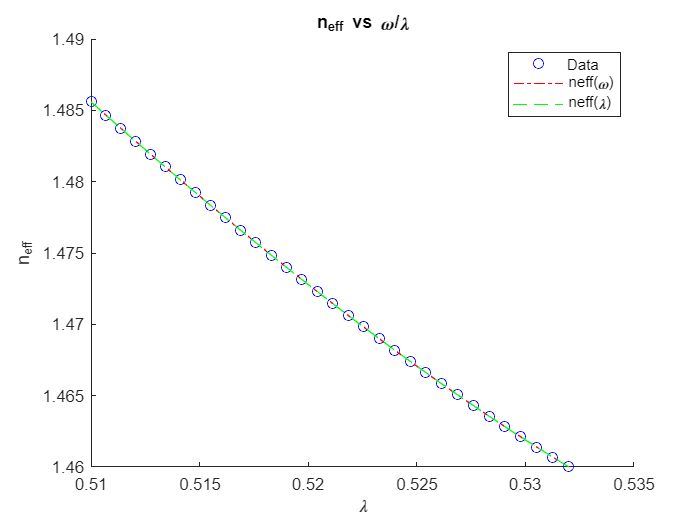

figure;
hold on
title("n_{eff} vs \omega/\lambda");
plot(l,neff,'bo',l,wgSuperior.neffwFun(w),'r-.',l,wgSuperior.nefflFun(l),'g--');
legend(["Data","neff(\omega)","neff(\lambda)"]);
xlabel("\lambda");
ylabel("n_{eff}");
hold off

#### Subfunctions (k, dw, Vg, d2w, D)

disp("Function k(ω):");

Function k(ω):


disp(wgSuperior.kwStr);

w.*(4.015345414268300587716790703345e-283*w.^30-3.327695710241664041153433773091e-273*w.^29+3.911579150467644275738474358677e-264*w.^28-1.131495000437115356053644122624e-254*w.^27-1.113015136524939495208315197258e-244*w.^26+2.503172924573330242941183824586e-234*w.^25+3.169357153935385342912886551177e-226*w.^24-3.221392517347102764978060102913e-215*w.^23-1.131974505280231019049456481927e-205*w.^22+2.902444113149587528518342781975e-196*w.^21+3.558648359421839222207801144410e-187*w.^20+3.825009732814392317818290145664e-177*w.^19+2.010025610938184616743160668166e-167*w.^18-5.553887193702539571747866549628e-158*w.^17-3.046980077643994320182790440942e-148*w.^16-8.236314495769926787792051523856e-140*w.^15-8.583080131984974889142501155272e-131*w.^14+6.479444299809742412741483814914e-120*w.^13+7.316737022263902165363012881036e-111*w.^12-1.347216457607635520433579425233e-101*w.^11+2.553838433279825556795826775284e-91*w.^10+2.849229161250202128848959876978e-82*w.^9-4.97359007326493332078982408771

disp("Function dk(ω)/dω:");

Function dk(ω)/dω:


disp(wgSuperior.dkwdwStr);

(4.015345414268300587716790703345e-283*w.^30*(31)-3.327695710241664041153433773091e-273*w.^29*(30)+3.911579150467644275738474358677e-264*w.^28*(29)-1.131495000437115356053644122624e-254*w.^27*(28)-1.113015136524939495208315197258e-244*w.^26*(27)+2.503172924573330242941183824586e-234*w.^25*(26)+3.169357153935385342912886551177e-226*w.^24*(25)-3.221392517347102764978060102913e-215*w.^23*(24)-1.131974505280231019049456481927e-205*w.^22*(23)+2.902444113149587528518342781975e-196*w.^21*(22)+3.558648359421839222207801144410e-187*w.^20*(21)+3.825009732814392317818290145664e-177*w.^19*(20)+2.010025610938184616743160668166e-167*w.^18*(19)-5.553887193702539571747866549628e-158*w.^17*(18)-3.046980077643994320182790440942e-148*w.^16*(17)-8.236314495769926787792051523856e-140*w.^15*(16)-8.583080131984974889142501155272e-131*w.^14*(15)+6.479444299809742412741483814914e-120*w.^13*(14)+7.316737022263902165363012881036e-111*w.^12*(13)-1.347216457607635520433579425233e-101*w.^11*(12)+2.55383843327982555

disp("Function Vg(ω):");

Function Vg(ω):


disp(wgSuperior.vgwStr);

(3*10^8)./(4.015345414268300587716790703345e-283*w.^30*(31)-3.327695710241664041153433773091e-273*w.^29*(30)+3.911579150467644275738474358677e-264*w.^28*(29)-1.131495000437115356053644122624e-254*w.^27*(28)-1.113015136524939495208315197258e-244*w.^26*(27)+2.503172924573330242941183824586e-234*w.^25*(26)+3.169357153935385342912886551177e-226*w.^24*(25)-3.221392517347102764978060102913e-215*w.^23*(24)-1.131974505280231019049456481927e-205*w.^22*(23)+2.902444113149587528518342781975e-196*w.^21*(22)+3.558648359421839222207801144410e-187*w.^20*(21)+3.825009732814392317818290145664e-177*w.^19*(20)+2.010025610938184616743160668166e-167*w.^18*(19)-5.553887193702539571747866549628e-158*w.^17*(18)-3.046980077643994320182790440942e-148*w.^16*(17)-8.236314495769926787792051523856e-140*w.^15*(16)-8.583080131984974889142501155272e-131*w.^14*(15)+6.479444299809742412741483814914e-120*w.^13*(14)+7.316737022263902165363012881036e-111*w.^12*(13)-1.347216457607635520433579425233e-101*w.^11*(12)+2.5538384

disp("Function d2k(ω)/dω2:");

Function d2k(ω)/dω2:


disp(wgSuperior.d2kwdw2Str);

(4.015345414268300587716790703345e-283*w.^29*(930)-3.327695710241664041153433773091e-273*w.^28*(870)+3.911579150467644275738474358677e-264*w.^27*(812)-1.131495000437115356053644122624e-254*w.^26*(756)-1.113015136524939495208315197258e-244*w.^25*(702)+2.503172924573330242941183824586e-234*w.^24*(650)+3.169357153935385342912886551177e-226*w.^23*(600)-3.221392517347102764978060102913e-215*w.^22*(552)-1.131974505280231019049456481927e-205*w.^21*(506)+2.902444113149587528518342781975e-196*w.^20*(462)+3.558648359421839222207801144410e-187*w.^19*(420)+3.825009732814392317818290145664e-177*w.^18*(380)+2.010025610938184616743160668166e-167*w.^17*(342)-5.553887193702539571747866549628e-158*w.^16*(306)-3.046980077643994320182790440942e-148*w.^15*(272)-8.236314495769926787792051523856e-140*w.^14*(240)-8.583080131984974889142501155272e-131*w.^13*(210)+6.479444299809742412741483814914e-120*w.^12*(182)+7.316737022263902165363012881036e-111*w.^11*(156)-1.347216457607635520433579425233e-101*w.^10*(132)

disp("Function D(ω):");

Function D(ω):


disp(wgSuperior.DwStr);

-(w.^2/(2*pi*3*10^8)).*((4.015345414268300587716790703345e-283*w.^29*(930)-3.327695710241664041153433773091e-273*w.^28*(870)+3.911579150467644275738474358677e-264*w.^27*(812)-1.131495000437115356053644122624e-254*w.^26*(756)-1.113015136524939495208315197258e-244*w.^25*(702)+2.503172924573330242941183824586e-234*w.^24*(650)+3.169357153935385342912886551177e-226*w.^23*(600)-3.221392517347102764978060102913e-215*w.^22*(552)-1.131974505280231019049456481927e-205*w.^21*(506)+2.902444113149587528518342781975e-196*w.^20*(462)+3.558648359421839222207801144410e-187*w.^19*(420)+3.825009732814392317818290145664e-177*w.^18*(380)+2.010025610938184616743160668166e-167*w.^17*(342)-5.553887193702539571747866549628e-158*w.^16*(306)-3.046980077643994320182790440942e-148*w.^15*(272)-8.236314495769926787792051523856e-140*w.^14*(240)-8.583080131984974889142501155272e-131*w.^13*(210)+6.479444299809742412741483814914e-120*w.^12*(182)+7.316737022263902165363012881036e-111*w.^11*(156)-1.34721645760763552043357

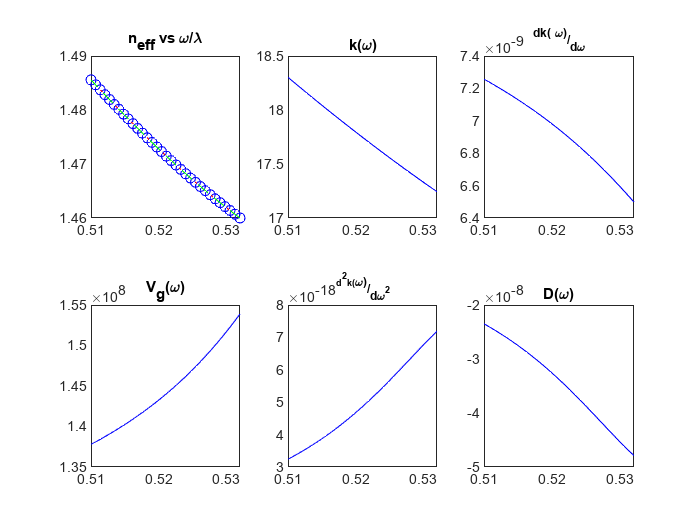

subplot(2,3,1);
plot(l,neff,'bo',l,wgSuperior.neffwFun(w),'r-.',l,wgSuperior.nefflFun(l),'g--');
title("n_{eff} vs \omega/\lambda");
subplot(2,3,2);
plot(l,wgSuperior.kwFun(w),'b');
title("k(\omega)");
subplot(2,3,3);
plot(l,wgSuperior.dkwdwFun(w),'b');
title("^{dk(\omega)}/_{d\omega}");
subplot(2,3,4);
plot(l,wgSuperior.vgwFun(w),'b');
title("V_g(\omega)");
subplot(2,3,5);
plot(l,wgSuperior.d2kwdw2Fun(w),'b');
title("^{d^2k(\omega)}/_{d\omega^2}");
subplot(2,3,6);
plot(l,wgSuperior.DwFun(w),'b');
title("D(\omega)");

##  Load Waveguide Simple:

 
file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
file = sprintf(Superior,sXs(sel),sYs(sel),mode);
load(SuperiorPath+file);
wgSuperior = waveguide(lambda,neff);

## K's comparing

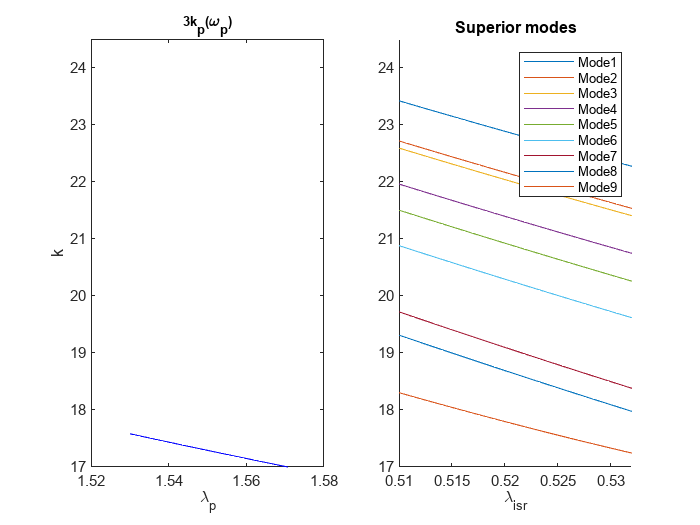

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
l = wgFundamental.lambdaData;
w = wgFundamental.omegaData;
neff = wgFundamental.neffData;
figure;
subplot(1,2,1)
plot(l,wgFundamental.kwFun(w).*3,'b');
leg = {};
title("3k_p(\omega_p)"); xlabel("\lambda_p"); ylabel("k");
ylim([17 24.5]);
subplot(1,2,2)
hold on
for i = 1:nmodes
    file = sprintf(Superior,sXs(sel),sYs(sel),i);
    load(SuperiorPath+file);
    wgSuperior = waveguide(lambda,neff);
    l = wgSuperior.lambdaData;
    w = wgSuperior.omegaData;
    plot(l,wgSuperior.kwFun(w));
    leg(end+1) = {"Mode"'+num2str(i)};
end
legend(leg);
ylim([17 24.5]);
title("Superior modes"); xlabel("\lambda_{isr}");
hold off

## Find degenerate photon that allow momentum and energy conservation

size=50;

lphLim = [min(wgFundamental.lambdaData) max(wgFundamental.lambdaData)];
lpLim = [min(wgSuperior.lambdaData) max(wgSuperior.lambdaData)];
lp = linspace(lpLim(1),lpLim(2),size);
wp = 2.*pi.*3.*10.^8./lp;
ws = wp./3;
leg = {};

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);

figure
hold on

dk0s = [];

for i = 1:nmodes
    file = sprintf(Superior,sXs(sel),sYs(sel),i);
    load(SuperiorPath+file);
    wgSuperior = waveguide(lambda,neff);
    %Nota w 10^8 es 10^14

    dk = wgSuperior.kwFun(wp)-(3*wgFundamental.kwFun(ws));

    if(min(dk)<=0 && max(dk)>=0)
        dk0s = [dk0s i];
    end

    plot(lp,dk);
    leg(end+1) = {"Mode"'+num2str(i)};
end

if ~isequal(dk0s,[])
    strDk0s = sprintf('Modo %i,',dk0s);
    strDk0s = "Modos con dK=0: "+strDk0s(1:end-1);
else
    strDk0s = "Ningun modo con dK=0";
end

disp(strDk0s)

Ningun modo con dK=0


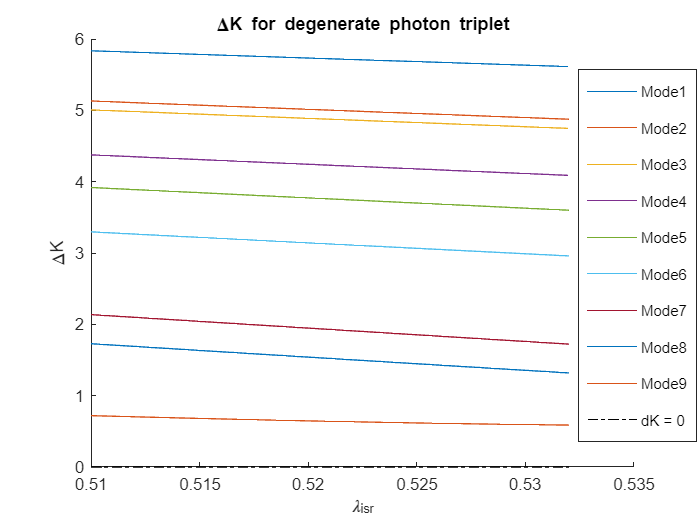


plot([lpLim(1),lpLim(2)],[0,0],'k-.')
leg(end+1) = {"dK = 0"};

legend(leg);
title("\DeltaK for degenerate photon triplet");
ylabel("\DeltaK"); xlabel("\lambda_{isr}");

legend("Position", [0.8256,0.15841,0.16964,0.70952])

## Phase Matching

switch nmodes
    case 15
        m = 5;n = 3;
    case 9
        m = 3;n = 3;
    case 19
        m = 5;n = 4;
    case 12
        m = 4;n = 3;
end

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);

lphLim = [min(wgFundamental.lambdaData) max(wgFundamental.lambdaData)];
lpLim = [min(wgSuperior.lambdaData) max(wgSuperior.lambdaData)];
li = 1.53;
size=50;

wp = linspace(2.*pi.*3.*10.^8./lpLim(1),2.*pi.*3.*10.^8./lpLim(2),size);
dw = linspace(1e8,-1e8,size);
[WP,DW] = meshgrid(wp,dw);
wi = (2.*pi.*3.*10.^8./li);
wr = DW+(WP-wi)/2;
ws = WP-wi-wr;

disp("Pump wavelength: "+num2str(lpLim(1))+"-"+num2str(lpLim(2)));

Pump wavelength: 0.51-0.532


disp("Photon wavelength: "+num2str(lphLim(1))+"-"+num2str(lphLim(2)));

Photon wavelength: 1.53-1.596


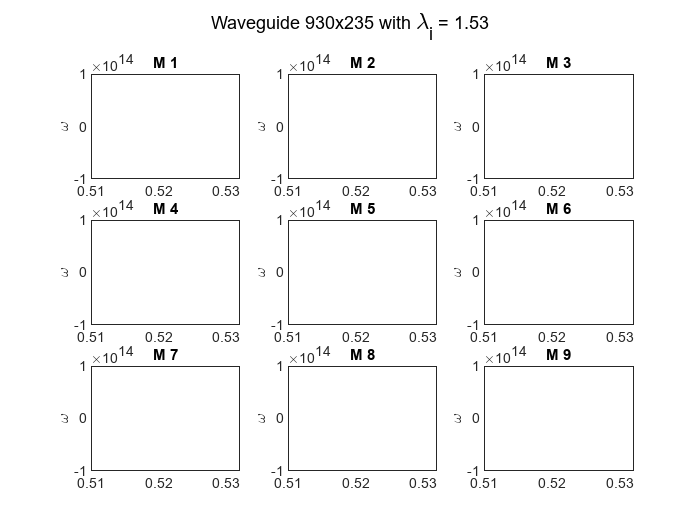

figure
for i = 1:nmodes
    file = sprintf(Superior,sXs(sel),sYs(sel),i);
    load(SuperiorPath+file);
    wgSuperior = waveguide(lambda,neff);
    %Nota w 10^8 es 10^14
    DK = wgSuperior.kwFun(WP)-(wgFundamental.kwFun(wi)+wgFundamental.kwFun(wr)+wgFundamental.kwFun(ws));
    subplot(m,n,i)
    contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'b','LineWidth',2);
    title("M "+num2str(i));
    ylabel("\omega");
end
sgtitle("Waveguide "+num2str(sXs(sel))+"x"+num2str(sYs(sel))+" with \lambda_i = "+num2str(li))